%% Especificaciones del filtro
fn = 50;          % Frecuencia central [Hz]
Q = 10;           % Factor de calidad
BW = 5;           % Ancho de banda 3dB [Hz]
wo = 2 * pi * fn; % Frecuencia angular central [rad/s]
bw_rad = 2 * pi * BW; % Ancho de banda en radianes/segundo

%% Función de transferencia del filtro rechaza-banda
% Coeficientes del denominador (forma estándar del filtro)
den = [1, wo/Q, wo^2]; % Denominador: s^2 + (wo/Q)*s + wo^2
% Coeficientes del numerador
num = [1, 0, wo^2];    % Numerador: s^2 + wo^2 (estructura notch)

% Crear la función de transferencia
Filtro = tf(num, den)

Filtro =
 
       s^2 + 9.87e04
  -----------------------
  s^2 + 31.42 s + 9.87e04
 
Continuous-time transfer function.



%% Descomposición manual en pasa-bajo y pasa-alto
% Filtro pasa-bajo
num_pb = [0, 0, wo^2]; % Numerador solo tiene la parte constante (s^0)
den_pb = den;          % Denominador igual al filtro original
PasaBajo = tf(num_pb, den_pb)

PasaBajo =
 
          9.87e04
  -----------------------
  s^2 + 31.42 s + 9.87e04
 
Continuous-time transfer function.




% Filtro pasa-alto
num_pa = [1, 0, 0];    % Numerador tiene solo la parte de s^2
den_pa = den;          % Denominador igual al filtro original
PasaAlto = tf(num_pa, den_pa)

PasaAlto =
 
            s^2
  -----------------------
  s^2 + 31.42 s + 9.87e04
 
Continuous-time transfer function.



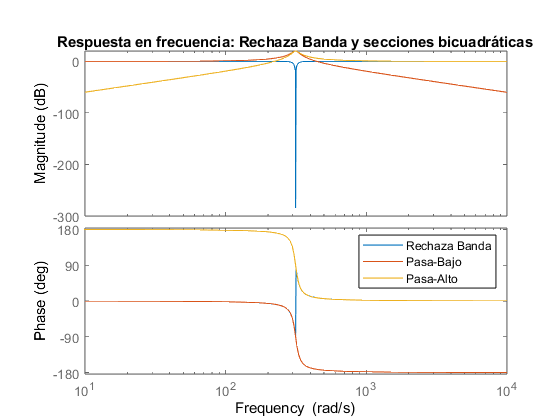


% Respuesta en frecuencia
figure;
bode(Filtro, PasaBajo, PasaAlto);
legend('Rechaza Banda', 'Pasa-Bajo', 'Pasa-Alto');
title('Respuesta en frecuencia: Rechaza Banda y secciones bicuadráticas');

% Diseño del filtro pasa bajo Sallen Key
syms C1 C2
%Establecemos valores de resistencias
R1=10e3

R1 = 10000

R2=10e3

R2 = 10000


%Planteamos las ecuaciones de wo y Q para calular C1 y C2
equ1= wo == 1/sqrt(R1*R2*C1*C2);
equ2= Q == sqrt(C1/C2)*sqrt(R1*R2)/(R1+R2);
sol=solve([equ1, equ2],[C1 C2]);
C1sol=double(sol.C1(2))

C1sol = 6.3662e-06

C2sol=double(sol.C2(2))

C2sol = 1.5915e-08

% Diseño del filtro pasa alto Sallen Key
syms R1 R2
%Establecemos valores de capacidad
C1=100e-9

C1 = 1.0000e-07

C2=100e-9

C2 = 1.0000e-07

k=1 %retroalimentacion unitaria

k = 1


%Planteamos las ecuaciones de wo y Q para calular R1 y R2
equ1= wo == 1/sqrt(R1*R2*C1*C2);
equ2= Q == 1/(sqrt(R1/R2)*((C1+C2)/(sqrt(C1*C2)))+(1-k)*sqrt((R2*C2)/(R1*C1)));
sol=solve([equ1, equ2],[R1 R2]);
R1sol=double(sol.R1(2))

R1sol = 1.5915e+03

R2sol=double(sol.R2(2))

R2sol = 6.3662e+05